# Scitran project reporting

Illustrates searching the Flywheel database from Matlab for subject information within a particular project.  

## 1. Authorization

Open the scitran object, here we name the instance 'vistalab'. This uses the URL of your Flywheel instance and the API key. 

st = scitran('stanfordlabs');

## 2. Search for all projects 

projects = st.search('projects', 'summary', true);

Number of projects found:  42


## 3. Plot number of sessions in each project

projectLabels = stProjectGet(st, projects, 'labels');
numSessions   = stProjectGet(st, projects, 'numsessions');

Recon Test : 1
Untitled_Test : 1
BCM_cohort2_scan2 : 5
PVL : 89
SOC ECoG (Hermes) : 4
READING YR8 : 78
EJ Apricot : 1
ALDIT : 17
SVIP (Philips) : 139
BCM_cohort1_scan1 : 98
VWFA FOV : 110
retinotopy : 2
HCP : 30
READING YR6 : 116
Templates Pediatric : 6
BCM_cohort3_scan1 : 23
VWFA : 4
KYEOM : 64
Sleep PO1 : 24
TBI: WRIISC : 5
Reading Longitude: DWI : 241
testproject : 12
Project 1 Test : 1
KYEOM Tier 3 : 75
UMN : 164
Autism Phenome : 625
Weston Havens : 35
Templates Macaque : 1
DES-fMRI : 23
Neonatal : 110
KYEOM Tier 2 : 49
DEMO : 2
BCM_cohort1_scan2 : 44
VWFA FOV Hebrew : 12
Templates Adult : 2
BCM_cohort2_scan1 : 28
ADNI: T1 : 1069
SVIP Released Data (SIEMENS) : 283
SVIP: Unreleased Data : 81
CHRI : 19
showdes : 23
Templates Neonatal : 12


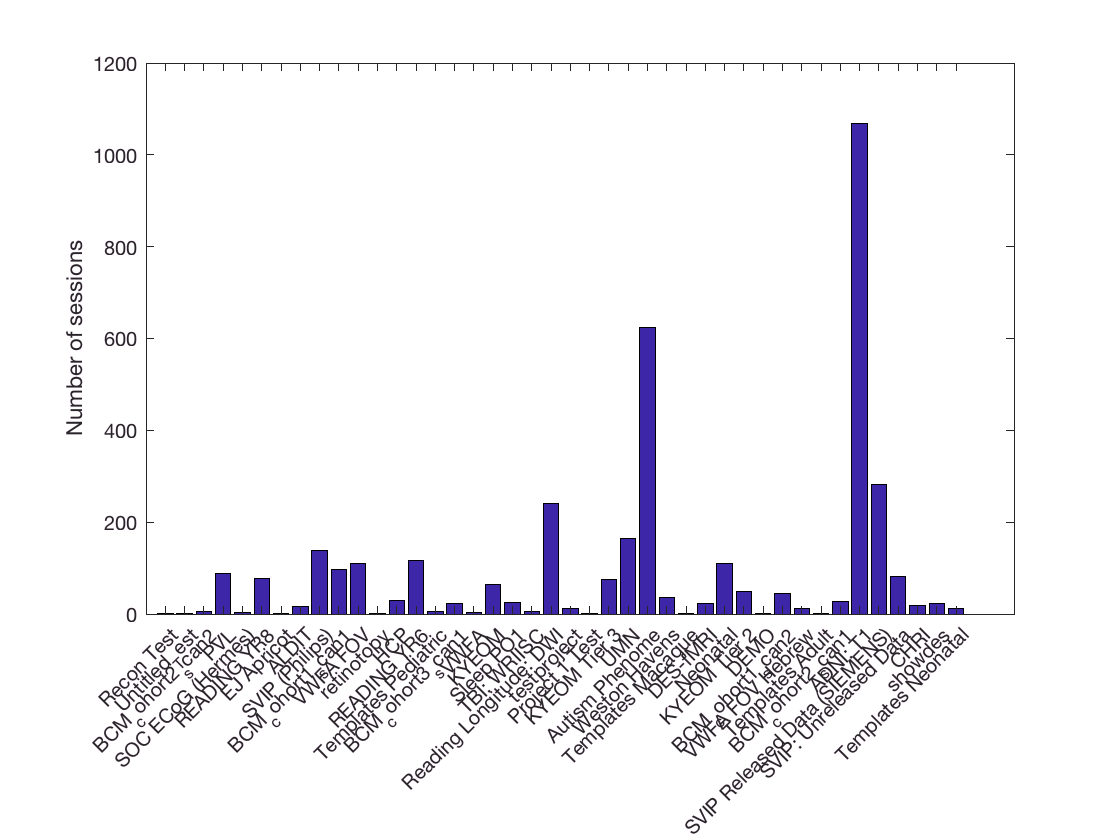


figure;
bar(numSessions);
set(gca,'XTick', 1:numel(projects), 'XTickLabels', projectLabels);
xtickangle(45);
ylabel('Number of sessions');

## 4. Search for sessions within a given project

    Find the sessions in the project, which contain the subject information

% project = 'SVIP Released Data (SIEMENS)';
project = 'VWFA FOV';
sessions = st.search('sessions','project label', project);
fprintf('Found %d sessions in the %s project.', length(sessions), project);

Found 110 sessions in the VWFA FOV project.

## 5. Parse the subject information

subjects = stSubjectInfo(sessions);
codes    = stSubjectGet(subjects,'code');
disp(codes);

    'ex9667'
    'ex10683'
    'ex13413'
    'ex10006'
    'ex11345'
    'ex10619'
    'ex13401'
    'ex11029'
    'ex8823'
    'ex10697'
    'ex10831'
    'ex10766'
    'ex8548'
    'ex11353'
    'ex10753'
    'ex8795'
    'ex4285'
    'ex13414'
    'ex10830'
    'ex9728'
    'ex9626'
    'ex8716'
    'ex8794'
    'ex8724'
    'ex9638'
    'ex8596'
    'ex10673'
    'ex8604'
    'ex11030'
    'ex10616'
    'ex6879'
    'ex11348'
    'ex6785'
    'ex10614'
    'ex10928'
    'ex4066'
    'wandell.vwfa'
    'ex8406'
    'ex9578'
    'ex9577'
    'ex13428'
    'wandell_vwfa'
    'ex11346'
    'ex6994'
    'ex10765'
    'ex9640'
    'ex9610'
    'ex8696'
    'ex4110'
    'ex10696'
    'ex7739'
    'ex9727'
    'ex9647'
    'ex4284'
    'ex11344'
    'ex10664'
    'ex8605'
    'ex11347'
    'ex8655'
    'ex11056'
    'ex8725'
    'ex8402'
    'ex10573'
    'ex10147'
    'ex8059'
    'ex9402'
    'ex8789'
    'ex10782'
    'ex8403'
    'ex9644'
    'ex9461'
    'ex6840'
    'ex8695'
    'ex1

## 6. Plot Sex Distribution

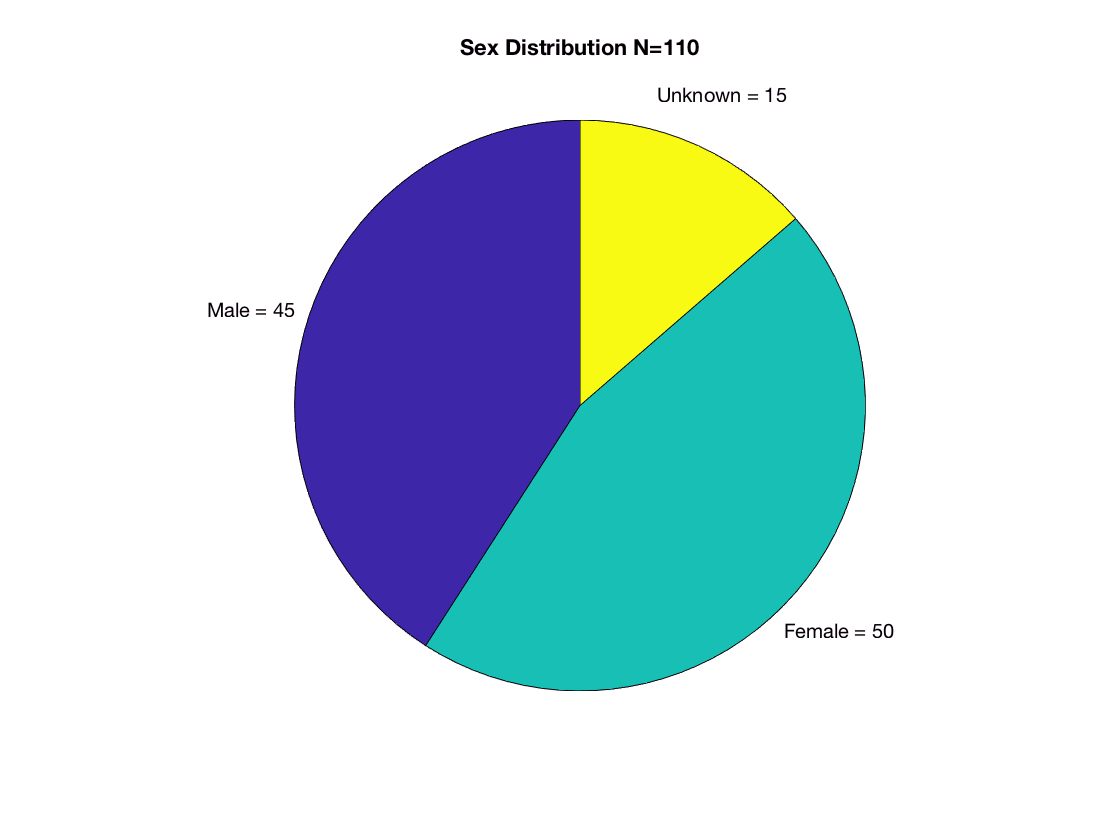

sex      = stSubjectGet(subjects,'sex');
nMale    = sum(sex=='m');
nFemale  = sum(sex =='f');
nUnknown = sum(sex == 'u');
labels = {['Male = ',    num2str(nMale)],...
          ['Female = ',  num2str(nFemale)],...
          ['Unknown = ', num2str(nUnknown)]};
pie([nMale, nFemale, nUnknown], labels);
title(['Sex Distribution N=', num2str(length(subjects))]);

## 7. Plot Age Distribution

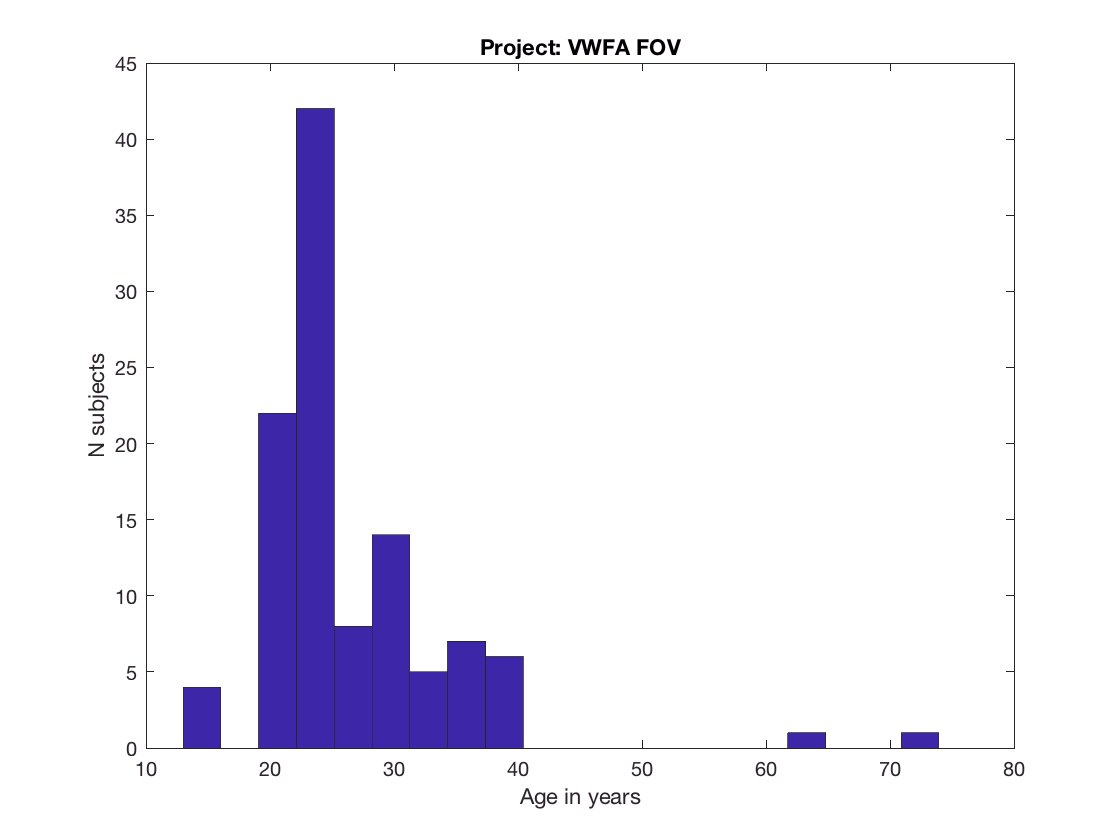

ages = stSubjectGet(subjects,'age');
figure; hist(ages,20); 
xlabel('Age in years'); ylabel('N subjects');
title(sprintf('Project: %s',project));